
close all;

%%%% Load datasets %%%
data_path = append(pwd,'\B0005.mat');
dataset = load(data_path);

battery = dataset.B0005.cycle;
battery = struct2cell(battery);
%data = battery(4,  6)
%plot(data{1}.Time, data{1}.Voltage_load)
%hist(data{1}.Voltage_load)
%hist(data{1}.Voltage_load)

discharge_count = 0;
for i = 1 : length(battery) 
    
    if ismember(battery(1,  i), {'discharge'}) == 1
        data = battery(4,  i);

        measured_v{discharge_count+1} = data{1}.Voltage_measured;
%         measured_v{discharge_count+1} = normalize(measured_v{discharge_count+1}, 'range');

        measured_c{discharge_count+1} = data{1}.Current_measured;

        load_v{discharge_count+1} = data{1}.Voltage_load;
%         load_v{discharge_count+1} = normalize(load_v{discharge_count+1}, 'range');

        load_c{discharge_count+1} = data{1}.Current_load;
%         load_c{discharge_count+1} = normalize(load_c{discharge_count+1}, 'range');

        temperature{discharge_count+1} = data{1}.Temperature_measured;
%         temperature{discharge_count+1} = normalize(temperature{discharge_count+1}, 'range');

        time{discharge_count+1} = data{1}.Time;

        capacity{discharge_count+1} = data{1}.Capacity;
        discharge_count = discharge_count + 1;

    end
end 

%%%%% histogram of the voltage, current , temperature, .... 
%%%%% Also finds the most ly appeared element in the specific cell array
%%%%% Actually I tried this method as a sampling, we can try other sampling
%%%%% methods which converst a N dim cell array to a single double

## Trying Gaussian outlier method rather than PCA

% We are using 2 Std
cleaned_combined_load_c = [];
for i = 1:length(load_c)
%     cleaned_combined_load_c = rmoutliers(load_c{i},'percentiles',[10 90]);
    cleaned_combined_load_c = [cleaned_combined_load_c mean(load_c{i})];
end

cleaned_combined_load_v = [];
for i = 1:length(load_v)
%     cleaned_combined_load_v = rmoutliers(load_c{i},'percentiles',[10 90]);
    cleaned_combined_load_v = [cleaned_combined_load_v mean(load_v{i})];
end

cleaned_combined_measured_c = [];
for i = 1:length(measured_c)
%     cleaned_combined_measured_c = rmoutliers(load_c{i},'percentiles',[10 90]);
    cleaned_combined_measured_c = [cleaned_combined_measured_c mean(measured_c{i})];
end

cleaned_combined_measured_v = [];
for i = 1:length(measured_v)
%     cleaned_combined_measured_v = rmoutliers(load_c{i},'percentiles',[10 90]);
    cleaned_combined_measured_v = [cleaned_combined_measured_v mean(measured_v{i})];
end

cleaned_combined_temperature = [];
for i = 1:length(temperature)
%     cleaned_combined_temperature = rmoutliers(load_c{i},'percentiles',[10 90]);
    cleaned_combined_temperature = [cleaned_combined_temperature mean(temperature{i})];
end

## Plot measured volt vs time

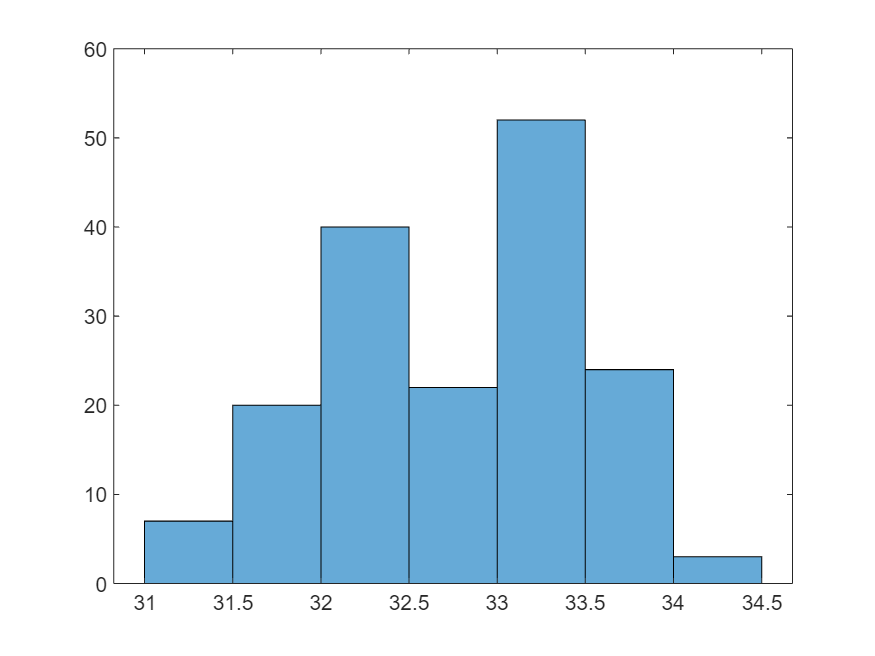

h = histogram(cleaned_combined_temperature);

## We can try other sampling methods. (Gibb's)

% h = histogram(load_c{168});
% % Retrieve some properties from the histogram
% V = h.Values
% E = h.BinEdges
% L = zeros(1, length(V))
% [x, y] = max(V)
% L (1, y) = 1
% L = logical(L)
% % Find the centers of the bins that identified as peaks
% left = E(L)
% right = E([false L])
% center = (left + right)/2 % the whole cell array might be replaced by this value ? 
% % Plot markers on those bins
% hold on
% plot(center, V(L), 'o')


%%%% SoC persentage %%%%

% charge_per = normalize([capacity{:}], 'range');
% figure;
% hold on;
% plot(1:168, charge_per);

## Training test split should be done (70% training data) for cross validation.

%%%% tried simple regression tree, looks like it works if the input and
%%%% labes cell array is the size.

## Trying random forest (ensemble of trees) regression. %%%%%

x = temperature{1}';
x1 = measured_v{1}';
x2 = measured_c{1}';

x3 = temperature{2}';
x4 = measured_v{2}';
x5 = measured_c{2}';

y = capacity{1} + 3*randn(size(capacity{1})) ;
x = [temperature{1}']

x =    24.3300
   24.3260
   24.3891
   24.5448
   24.7314
   24.9098
   25.1059
   25.3170
   25.5094
   25.7036


(load_c{1}) %gets the temperature values of 168.cell

ans =    -0.0006   -0.0006   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982


temperature(168) %gets 168. cell of temperature

ans = 1×1 cell array
    {[25.0933 25.1044 25.1062 25.1788 25.2760 25.4024 25.4996 25.6087 25.7239 25.8371 25.9484 26.0860 26.2116 26.3213 26.4275 26.5573 26.6717 26.7740 26.9106 27.0242 27.1422 27.2509 27.3604 27.4616 27.5636 27.6873 27.8098 27.9145 28.0324 28.1413 28.2467 28.3484 28.4649 28.5734 28.6814 28.7637 28.8720 28.9750 29.0960 29.1908 29.2721 29.3815 29.4607 29.5664 29.6752 29.7606 29.8374 29.9071 30.0057 30.0958 30.1619 30.1888 30.2544 30.3026 30.3724 30.3860 30.4052 30.4751 30.5234 30.5325 30.5702 30.5588 30.5835 30.6324 30.6557 30.6868 30.7063 30.6681 30.7365 30.7591 30.7797 30.8189 30.8245 30.8366 30.8595 30.9008 30.9057 30.9481 30.9755 30.9948 31.0134 31.0766 31.0793 31.1292 31.1653 31.1933 31.2733 31.3096 31.3542 31.4029 31.4439 31.4936 31.5417 31.5717 31.5844 31.6235 31.7039 31.7406 31.8149 31.8544 31.8869 31.9367 31.9641 31.9878 32.0934 32.1322 32.1685 32.2072 32.3020 32.2774 32.3205 32.3594 32.4349 32.4905 32.5461 32.5744 32.6613 32.7048 32.7464 32.8183 32.8352 32.81

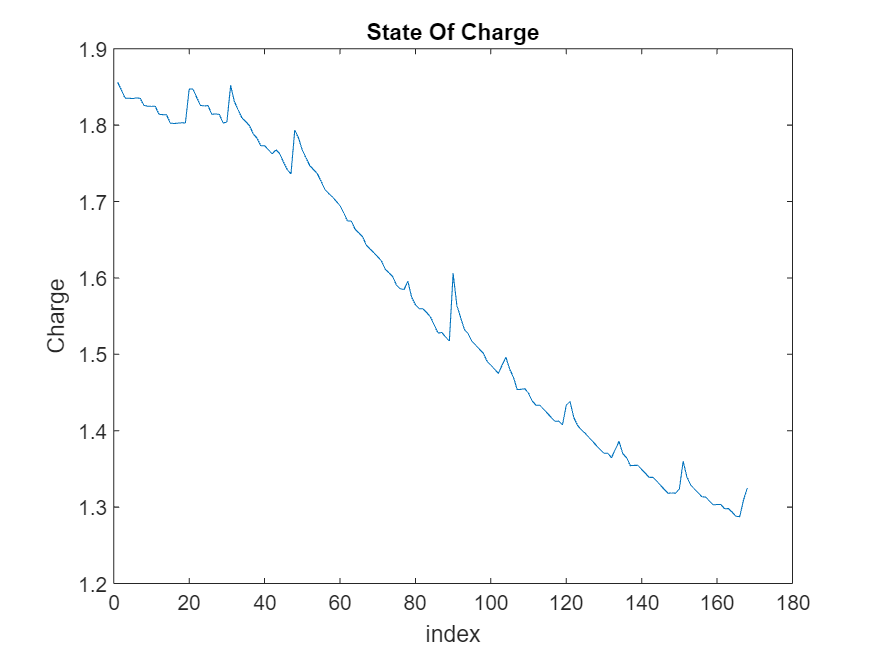


plot(1:length([capacity{:}]), [capacity{:}])
xlabel('index')
ylabel('Charge')
title('State Of Charge')




%x = [1;30;45;61;177;2;33;4;44;234;356;4;2;3;42;2;3;59;68;81;1;30;45;59;68;81]
% 
% x1 = [177;2;33;4;177;2;33;4;44;234;356;4;2;3;42;2;3;44;234;356;4;2;3;42;2;3];
% x2 = [157;2;353;4;157;2;53;4;44;534;356;4;2;53;52;2;3;44;235;556;4;252;53;42;2;3];
% y = [22,44,61,80,120,22,44,61,80,120,133,145,44,61,44,61,133,145,133,145,44,61,44,61,133,145];
% 
% tree = fitrtree([x x1 x2],y ,...
%                 'CategoricalPredictors',3,'MinParentSize',5,...
%                 'PredictorNames',{'x','x1', 'x2'});
% Ynew = predict(tree, [x3 x4 x5])

%view(tree,'Mode','graph');